# Create Simulink Environment and Train Agent

This example shows how to convert the PI controller in the `watertank` Simulink® model to a reinforcement learning deep deterministic policy gradient (DDPG) agent. For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Balance Double Integrator Environment](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Water Tank Model

The original model for this example is the water tank model. The goal is to control the level of the water in the tank. For more information about the water tank model, see [watertank Simulink Model](docid:slcontrol_gs#bsp4o3g).

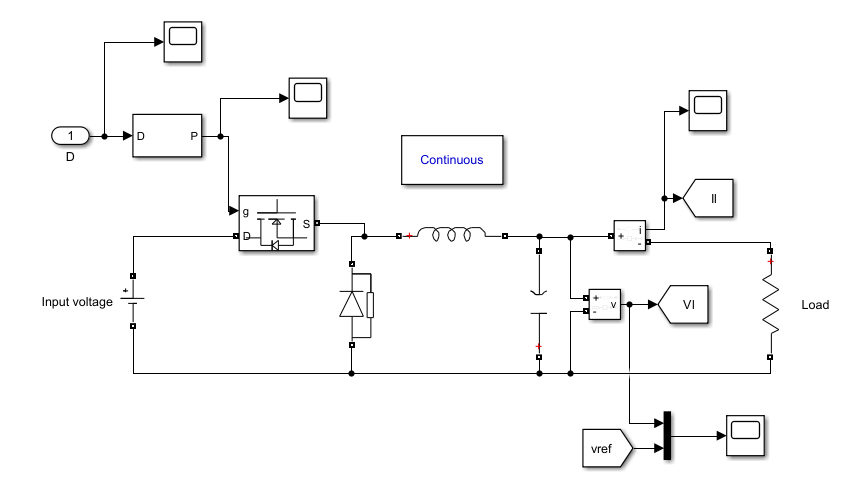

Modify the original model by making the following changes:

- Delete the PID Controller.

- Insert the RL Agent block.

- Connect the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & h
\end{array}\right\rbrack }^{T\;}$, where $h$ is the height of the tank, $e=r-h$, and $r$ is the reference height.

- Set up the reward $\textrm{reward}=10\left(\left|e\right|<0\ldotp 1\right)-1\left(\left|e\right|\ge 0\ldotp 1\right)-100\left(h\le 0\left|\right|h\ge 20\right)$.

- Configure the termination signal such that the simulation stops if $h\le 0$ or $h\ge 20$.

The resulting model is `rlwatertank.slx`. For more information on this model and the changes, see [Create Simulink Environment for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

open_system('RL_Renewable_energy_smoothing')
load('wind_data.mat');

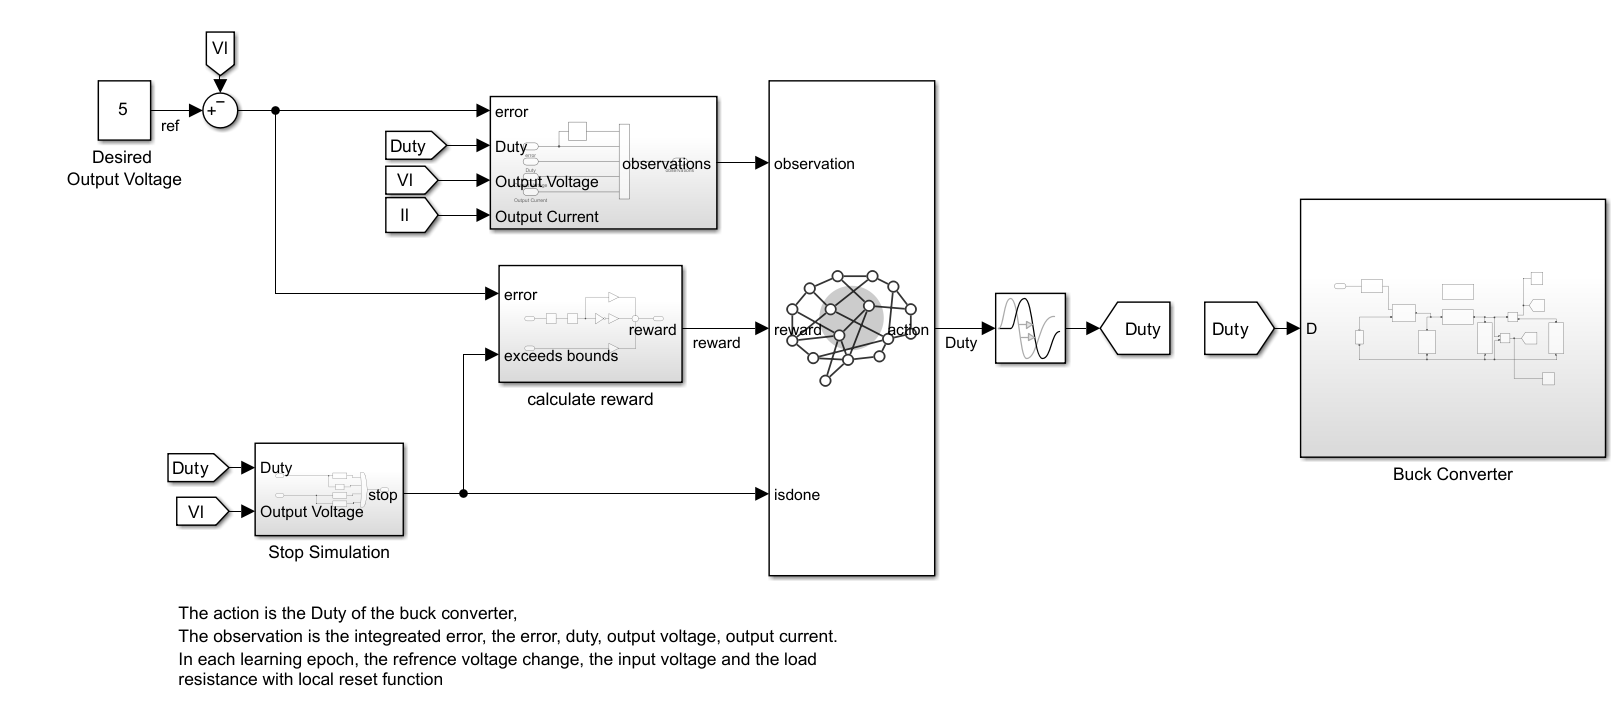

## Create the Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

obsInfo = rlNumericSpec([6 1],...
    LowerLimit=[0 0 0 -3 -1000 -0.15]',...
    UpperLimit=[3 3 3  3 0 0.15]');
obsInfo.Name = "observations";
obsInfo.Description = "las_smoothing, D_F1, D_F2, wind_power";

actInfo = rlNumericSpec([1 1],...
    LowerLimit=[-0.1]',...
    UpperLimit=[0.1]');
actInfo.Name = "P_smooth";

Build the environment interface object.

env = rlSimulinkEnv("RL_Renewable_energy_smoothing","RL_Renewable_energy_smoothing/RL Agent",...
    obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.01;
%Tf = 1800;
Tf =30;

Fix the random generator seed for reproducibility.

rng(0,"twister");

## Create the Critic

Given observations and actions, a DDPG agent approximates the long-term reward using a value function approximator as a critic.

Create a deep neural network to approximate the value function within the critic. To create a network with two inputs, the observation and action, and one output, the value, use three different paths, and specify each path as a row vector of layer objects. You can obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

% scale factor of layer size to sudy size impact 
scale_factor=1;
sequance_length_value=1;
observationPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="observation")
    %sequenceInputLayer(obsInfo.Dimension(1),Name="observation",Normalization="rescale-symmetric")
    concatenationLayer(1,2,Name="concat")
    %lstmLayer(sequance_length_value,OutputMode="sequence")
    fullyConnectedLayer(scale_factor*256)
    reluLayer
    fullyConnectedLayer(scale_factor*128)
    reluLayer
    fullyConnectedLayer(scale_factor*64)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(actInfo.Dimension(1),Name="action",Normalization="rescale-symmetric");
%actionPath =sequenceInputLayer(actInfo.Dimension(1),Name="action",Normalization="rescale-symmetric")
criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"action","concat/in2");


View the critic network configuration.

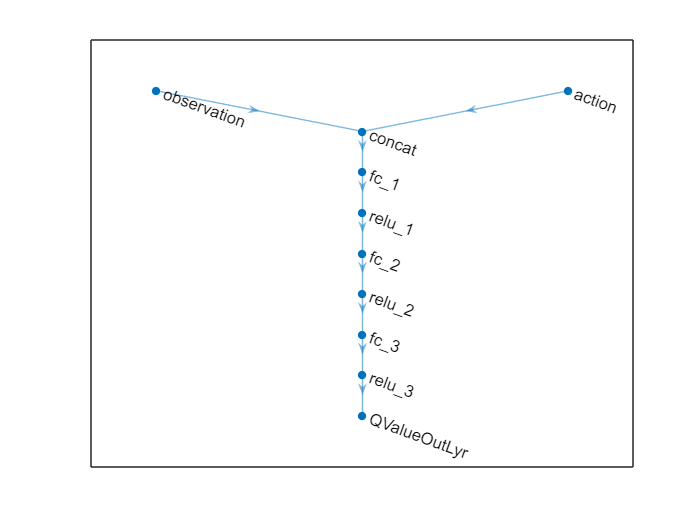

figure
plot(criticNet)

Convert the network to a `dlnetwork` object and summarize its properties.

summary(initialize(criticNet))


   Initialized: true

   Number of learnables: 43.2k

   Inputs:
      1   'observation'   6 features
      2   'action'        1 features



Create the critic approximator object using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels. 

critic1 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation", ...
    ActionInputNames="action");
critic2 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation", ...
    ActionInputNames="action");
critic1.UseDevice="gpu";
critic2.UseDevice="gpu";
rng(0,"twister");

For more information on Q-value function objects, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

Check the critic with a random input observation and action.

% getValue(critic, ...
%     {rand(obsInfo.Dimension)}, ...
%     {rand(actInfo.Dimension)})

For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the Actor

Given observations, a DDPG agent decides which action to take using a deterministic policy, which is implemented by an actor.

Create a deep neural network to approximate the policy within the actor. To create a network with one input, the observation, and one output, the action, a row vector of layer objects. You can obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

commonPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="observation")
    %sequenceInputLayer(obsInfo.Dimension(1),Name="observation",Normalization="rescale-symmetric")
    %lstmLayer(sequance_length_value,OutputMode="sequence")
    fullyConnectedLayer(scale_factor*256)
    reluLayer
    fullyConnectedLayer(scale_factor*128)
    reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(scale_factor*64,Name="meanFC")
    reluLayer
    fullyConnectedLayer(actInfo.Dimension(1),Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(actInfo.Dimension(1),Name="stdFC")
    reluLayer
    softplusLayer(Name="actionStd")
    ];

actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"commonPath","meanFC/in");
actorNet = connectLayers(actorNet,"commonPath","stdFC/in");

Convert the network to a `dlnetwork` object and summarize its properties.

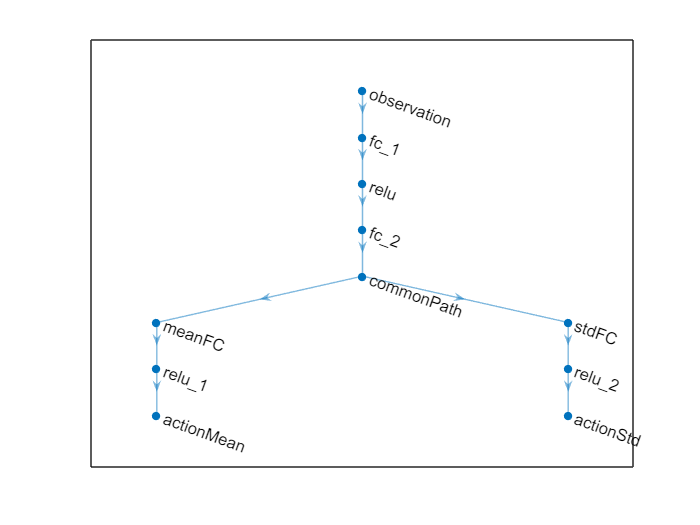

plot(actorNet)

actorNet = initialize(actorNet);
summary(actorNet)


   Initialized: true

   Number of learnables: 43.1k

   Inputs:
      1   'observation'   6 features



Create the actor approximator object using the specified deep neural network, the environment specification objects, and the name if the network input to be associated with the observation channel. 

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd");
actor.UseDevice="gpu";
gpurng(0)

For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3). 

Check the actor with a random input observation.

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.76517]}


For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the DDPG Agent

Create the DDPG agent using the specified actor and critic approximator objects.

agentOpts = rlSACAgentOptions( ...
    SampleTime             = Ts, ...
    ExperienceBufferLength = 1e6, ...
    NumWarmStartSteps      = 1e3, ...
    MiniBatchSize          = 150,...
    DiscountFactor=0.1,...
    SequenceLength= sequance_length_value);

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;
%agentOpts.ActorOptimizerOptions.L2RegularizationFactor=1e-5;
for ct = 1:2
    agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
    agentOpts.CriticOptimizerOptions(ct).LearnRate =5e-4;
    agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
end
rng(0,"twister");
agent = rlSACAgent(actor,[critic1,critic2],agentOpts);
agent.AgentOptions.EntropyWeightOptions.TargetEntropy=-5;
%agent.AgentOptions.EntropyWeightOptions.GradientThreshold=1;
%agent.AgentOptions.InfoToSave.ExperienceBuffer=true;
%agent.AgentOptions.InfoToSave.Optimizer=true;
%agent.AgentOptions.InfoToSave.PolicyState=true;
%agent.AgentOptions.InfoToSave.Target=true;

%agent.AgentOptions.NumStepsToLookAhead=2;
%agent.AgentOptions.NumEpoch=2;
%agent.AgentOptions.MaxMiniBatchPerEpoch=100;
% agent.AgentOptions.TargetSmoothFactor=2e-3;


For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef). 

Specify options for the agent, the actor, and the critic using dot notation.

% agent.SampleTime = Ts;
% 
% agent.AgentOptions.TargetSmoothFactor = 1e-3;
% agent.AgentOptions.DiscountFactor = 0.5;
% agent.AgentOptions.MiniBatchSize = 64;
% agent.AgentOptions.ExperienceBufferLength = 1e6; 
% 
% agent.AgentOptions.NoiseOptions.Variance = 1.0;
% agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;
% 
% agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-04;
% agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
% agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
% agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Alternatively, you can specify the agent options using an [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c) object.

Check the agent with a random input observation.

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.0052896]}


## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes. Specify that each episode lasts for at most `ceil(Tf/Ts)` (that is `200`) time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `800` over `20` consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

% trainOpts = rlTrainingOptions(...
%     MaxEpisodes=400, ...
%     MaxStepsPerEpisode=ceil(Tf/Ts), ...
%     ScoreAveragingWindowLength=2, ...
%     Verbose=false, ...
%     Plots="training-progress",...
%     StopTrainingCriteria="AverageReward",...
%     StopTrainingValue=4000);
% trainOpts.UseParallel = false;

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    StopTrainingCriteria="EvaluationStatistic", ...
    StopTrainingValue=3120, ...
    SimulationStorageType="none", ...
    SaveAgentCriteria="EvaluationStatistic",...
    SaveAgentValue=2500);
trainOpts.UseParallel =true;
trainOpts.ParallelizationOptions.Mode = "async";
trainOpts.ParallelizationOptions.WorkerRandomSeeds=-1;
evl = rlEvaluator(EvaluationFrequency=30, NumEpisodes=5);

logger = rlDataLogger();
logger.AgentLearnFinishedFcn = @logAgentLearnData;

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainResult = train(agent, env, ...
        trainOpts, ...
        Logger    = logger, ...
        Evaluator = evl);
else
    % Load the pretrained agent for the example.
%     load("WaterTankDDPG.mat","agent")
%remove the oscilating par due to the exploration;
%agent.UseExplorationPolicy = false;
end

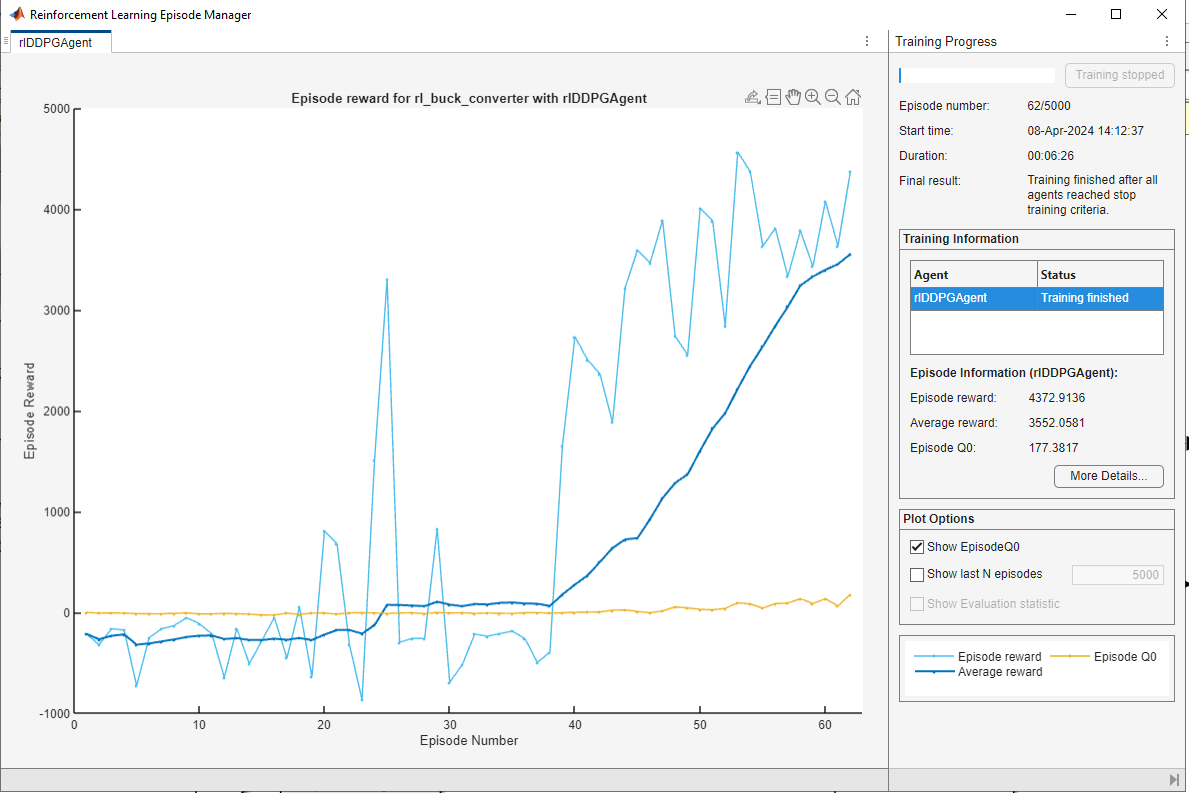

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);

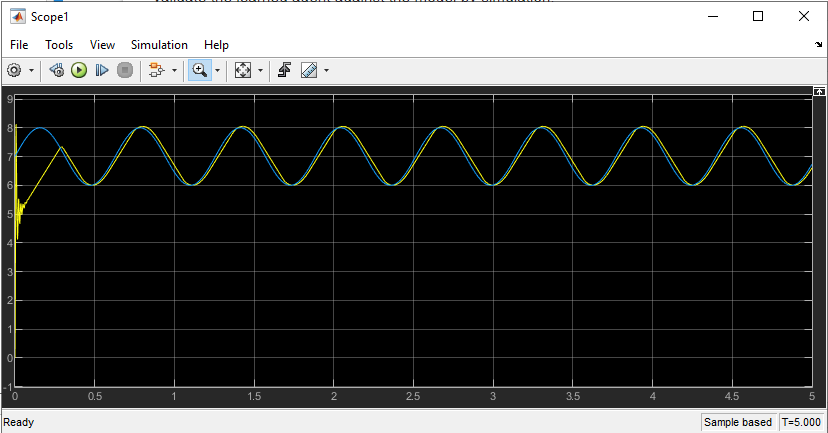

## Local Function

function in = localResetFcn(in)

% % randomize the studied window
% % define the length of the widnow of each iteration 
% Window_length=100;
% indexr= randi([1 length(WindProfile_total.Time)-Window_length],1,1);
% WindProfile = timeseries(WindProfile_total.Data(indexr:indexr + Window_length-1),1:length(WindProfile_total.Data(indexr:indexr + Window_length-1)));
end

**Data Logging Functions**

function dataToLog = logAgentLearnData(data)
% This function is executed after completion
% of the agent's learning subroutine.
dataToLog.ActorLoss = data.ActorLoss;
dataToLog.CriticLoss = data.CriticLoss;
end

*Copyright 2019 The MathWorks, Inc.*